# Taratura manuale dell'anello di velocità

Determinare $C(s)$ in modo che soddisfi una frequenza di taglio desirata

In quest'esempio il controllore è un PI


$$C(s)=PI(s)=\frac{K_p\cdot s+K_i}{s}=K_p\left(1+\frac{1}{T_i s}\right)=K_p \frac{T_i s +1}{T_i s}$$


il processo è la funzione di trasferimento, in questo caso coppia - velocità lato motore

clear all;close all;clc;
load modello_continuo_j1_ss.mat
sys_vel_motore=tf(modello_continuo_j1_ss);

Con funzione di trasferimento

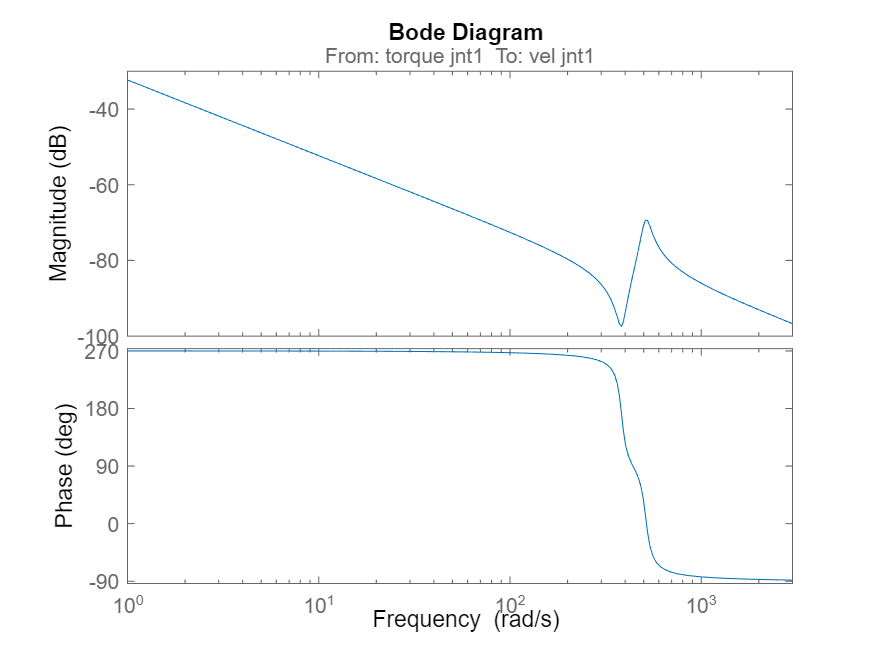

figure
bode(sys_vel_motore)
xlim([1 3000])

Vorrei un $\omega_c$ prossima all'antirisonanza (che è attorno a 200 rad/s)

wc=100;

L'azione integrale mi sfasa, la metto almeno una decade prima.

wi=wc/5; % pulsazione azione integrale
Ti=1/wi;

Il mio controllore sarà


$$C(s)=K_p \left(1+1/(Ti\cdot s)\right)=K_p C_o(s)$$


con $C_o(s)=$

s=tf('s');
Co=1+1/(Ti*s);

Calcolo $K_p$ in modo che $C(s)*P(s)=K_p \left(C_o(s)*P(s)\right)$ abbia modulo 1 in $\omega_c$. 

$|K_p \left(C_o(j\omega_c)*P(j\omega_c)\right)|=1 $ quindi $K_p=1/| \left(C_o(j\omega_c)*P(j\omega_c)\right)|$

Kp=1/abs(freqresp(Co*sys_vel_motore,wc));
C=Kp*Co

C =
 
  208.9 s + 4177
  --------------
      0.05 s
 
Continuous-time transfer function.



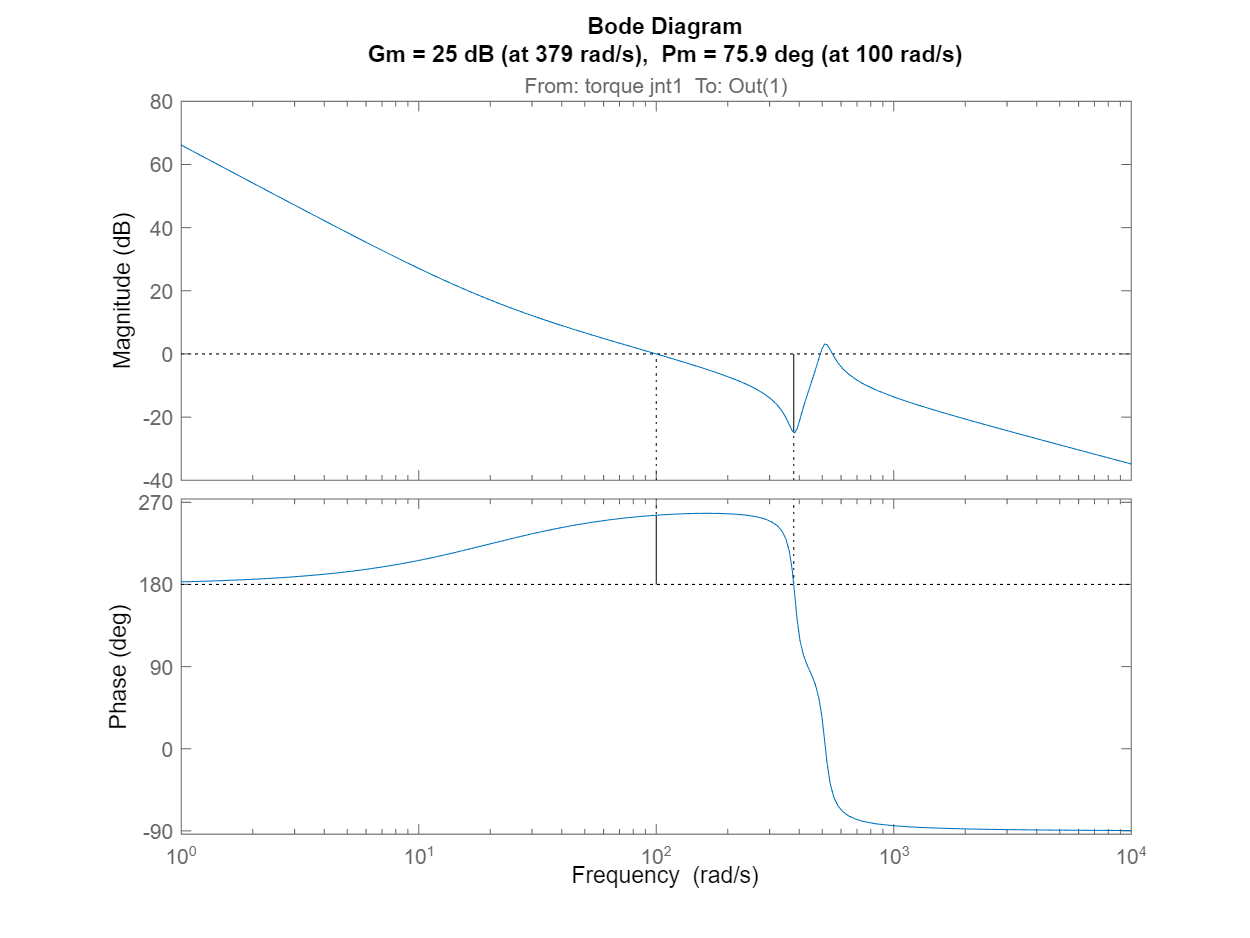

figure
margin(C*sys_vel_motore)

Il diagramma di bode taglia più volte, meglio aggiungere un filtro per abbassare il picco.

#### Filtro Notch

Un filtro notch è un'elimina banda. La zona da eliminare è 

damp(sys_vel_motore)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -2.06e-11                 1.00e+00       2.06e-11         4.86e+10    
 -2.79e+01 + 5.12e+02i     5.45e-02       5.12e+02         3.58e-02    
 -2.79e+01 - 5.12e+02i     5.45e-02       5.12e+02         3.58e-02    


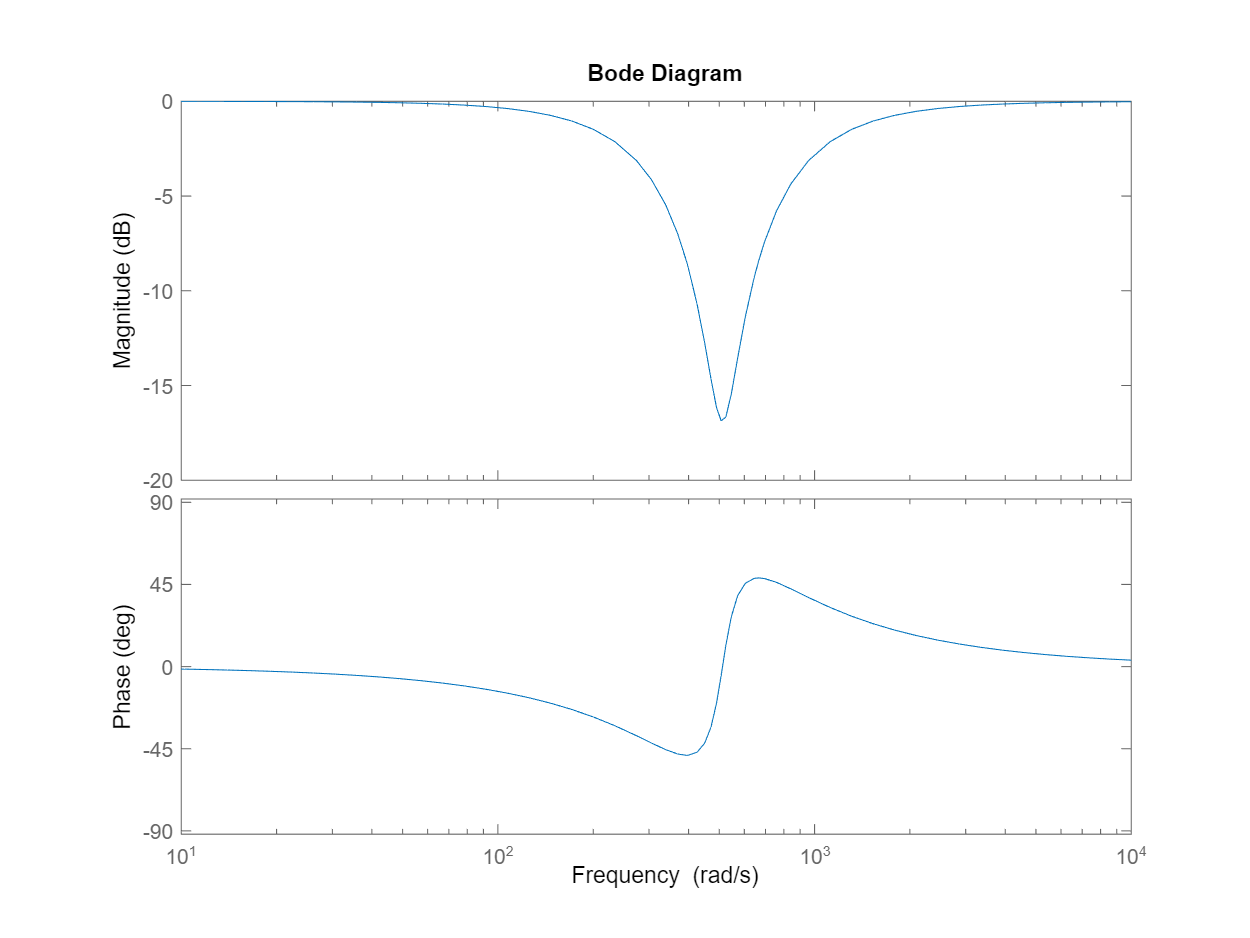

wn=512;
xci_z=0.1; %aggiustate xci_z e xci_p per rendere il filtro più o meno selettivo
xci_p=0.7;
notch=(s^2+2*xci_z*wn*s+wn^2)/(s^2+2*xci_p*wn*s+wn^2);
figure
bode(notch)

Per il PI, il "nuovo" sistema da controllare è

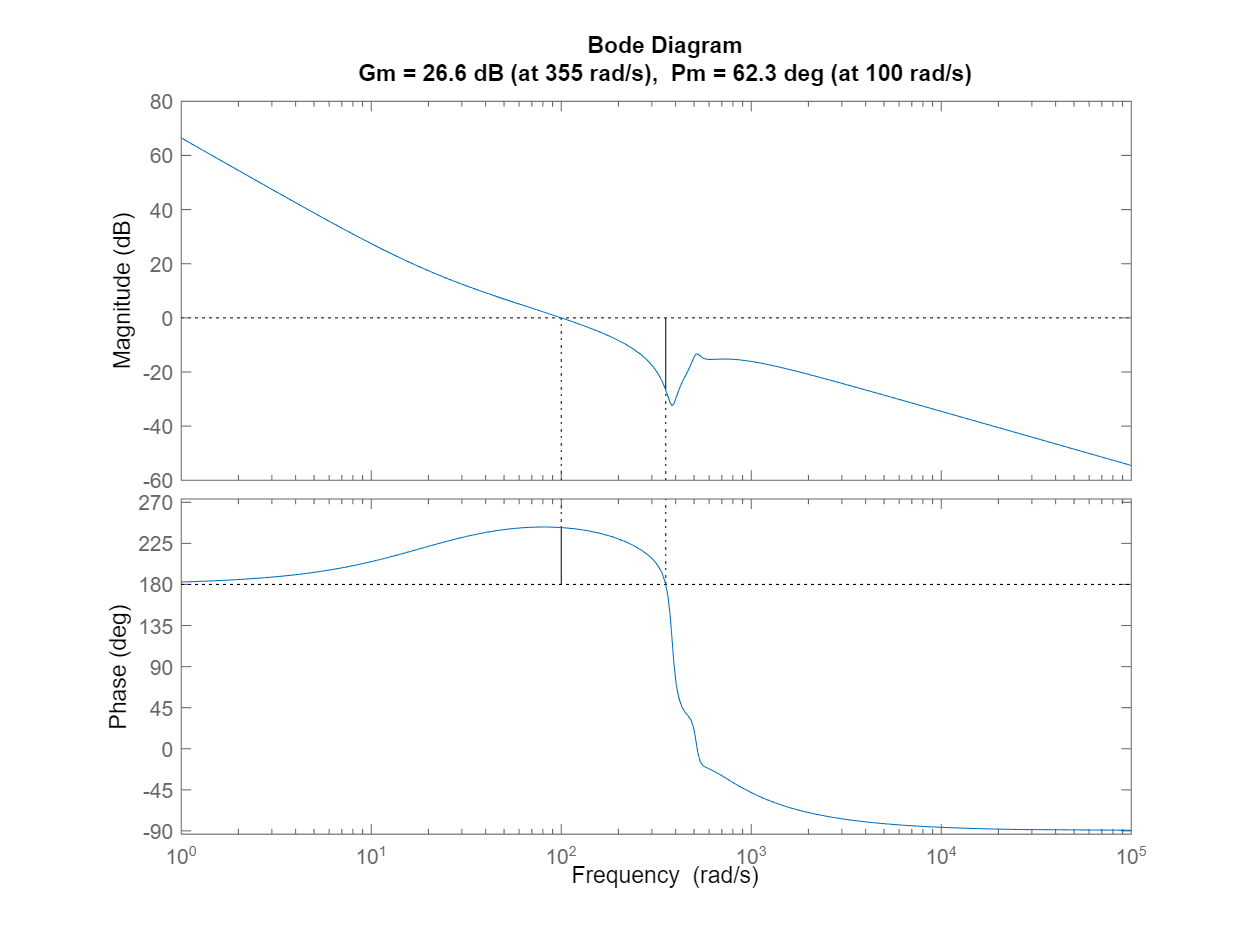

P=sys_vel_motore*notch;
Kp=1/abs(freqresp(Co*P,wc));
C=Kp*Co;
figure
margin(C*P)

Potrei voler aggiungere altri poli (ad esempio un passa basso)